# [Deploy Machine Learning](https://apmonitor.com/pds/index.php/Main/DeployMachineLearning)

Training and testing are often performed once on a dedicated computing platform. The trained model is then packaged for another computing system for predictions. An example of this training and deployment is the [**Tesla Autopilot**](https://www.tesla.com/AI) as demonstrated in the [**Tesla AI Day**](https://youtu.be/j0z4FweCy4M).

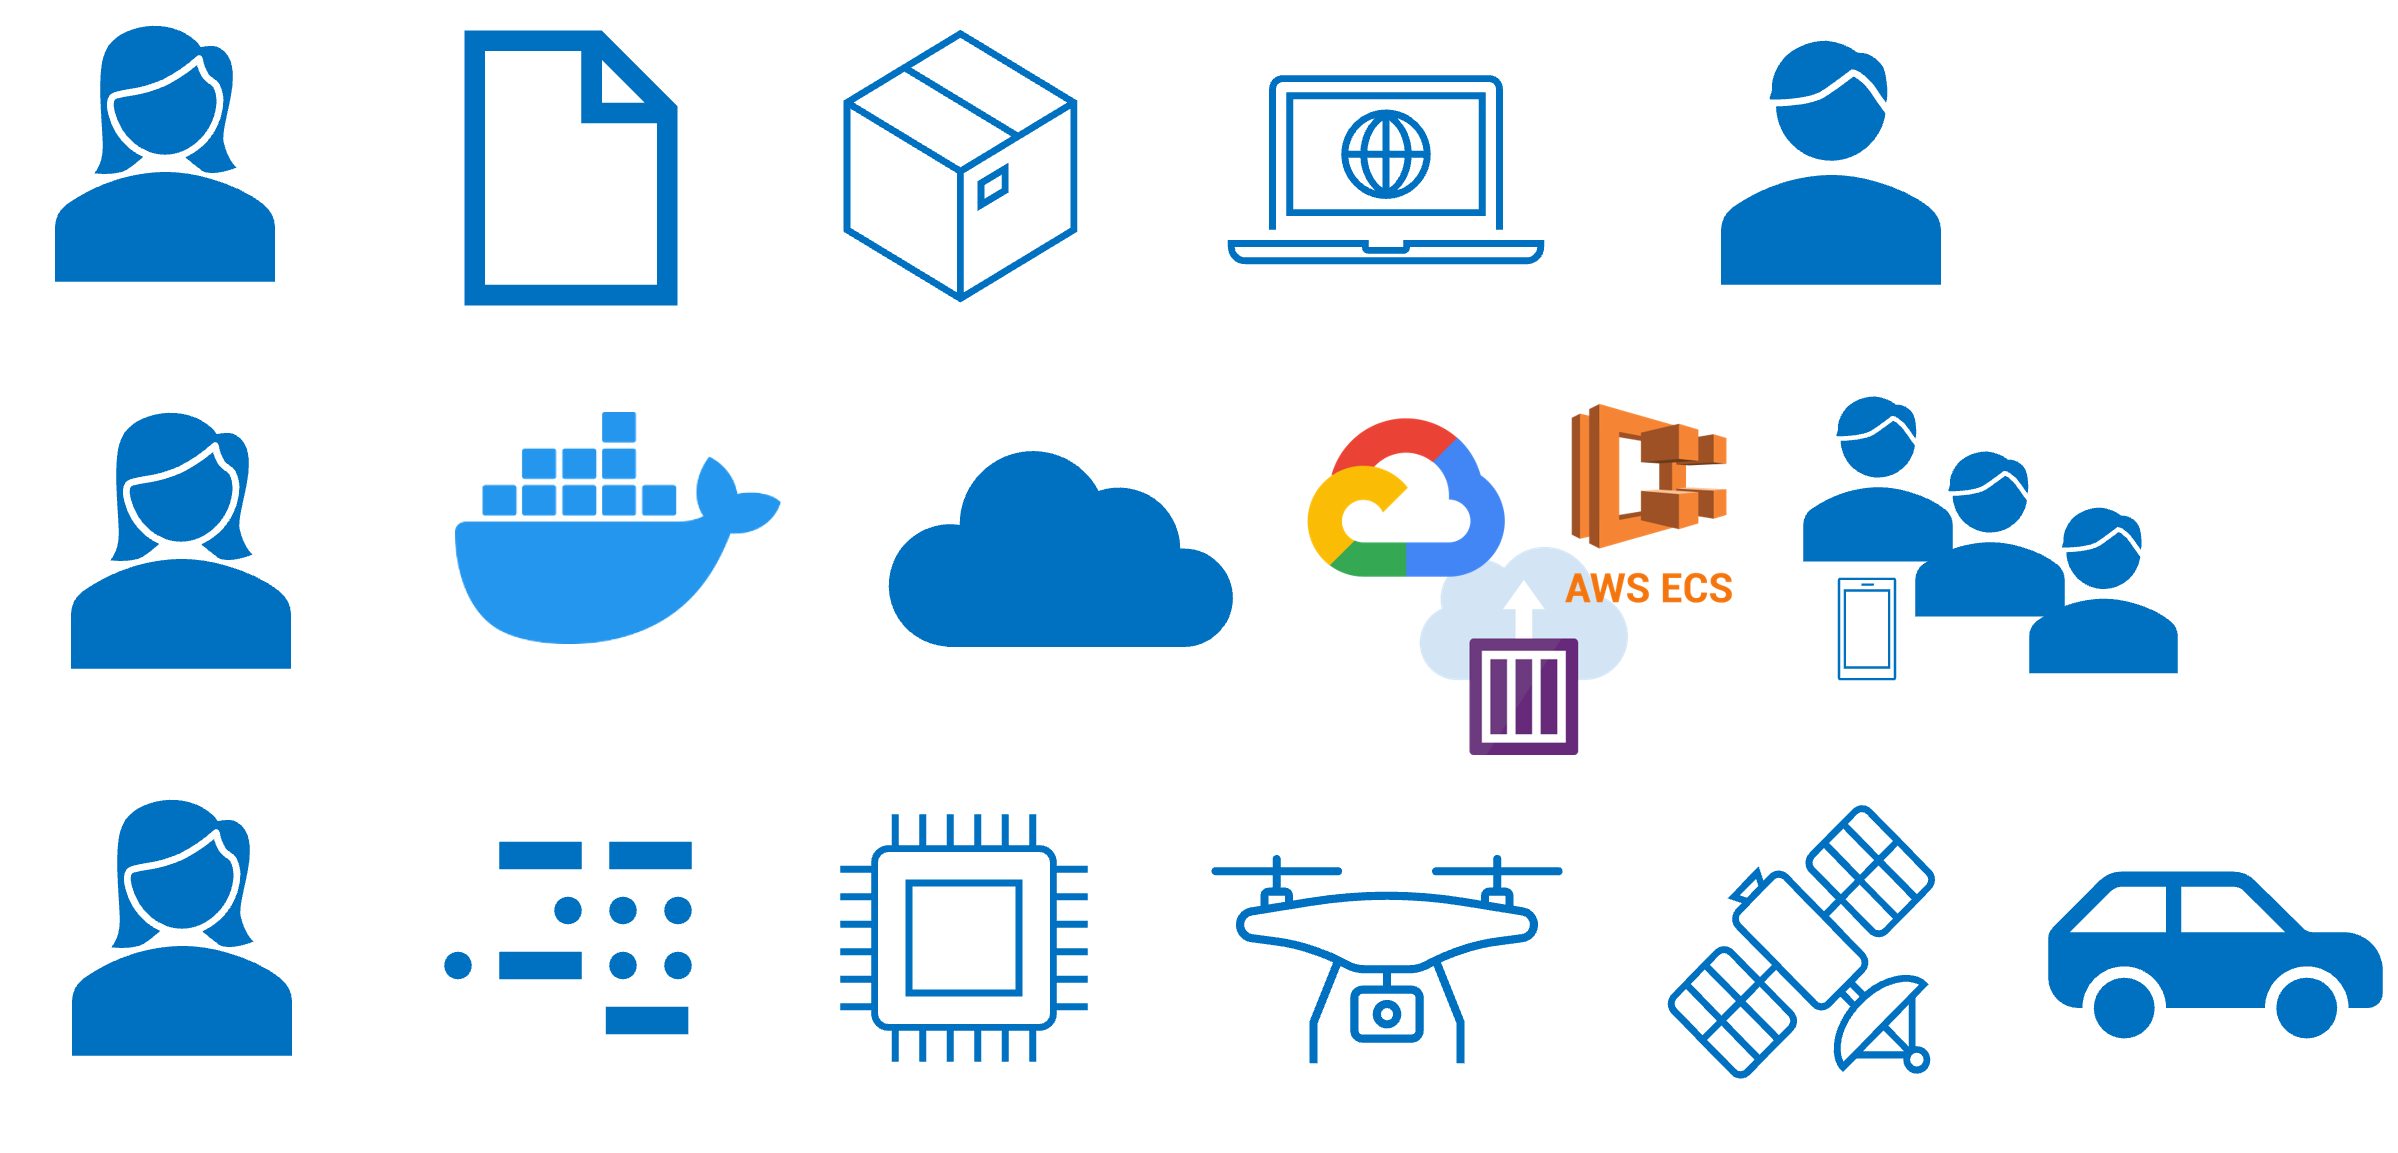

Deploying machine learning is the process of making the model available to produce results for people or computers to access the model predictions. It involves managing data flow to the application for training or prediction. Data flow can be in batches or a continuous stream.

If the machine learned model is trained offline, the model is encapsulated and transferred to the hosting target. A scalable deployment means that the computing architecture can handle increased demand such as through a cloud computing host with on-demand scale-up. A [**Docker container**](https://docs.docker.com/language/python/deploy/) can be deployed to cloud services.

- [**Google Cloud**](https://cloud.google.com/compute/docs/containers)

- [**Azure Container Instances (ACI)**](https://azure.microsoft.com/en-us/services/container-instances/#overview)

- [**Amazon Elastic Container Service (ECS)**](https://aws.amazon.com/ecs/)

You can read more about Docker containers in MATLAB [here](https://www.mathworks.com/help/cloudcenter/ug/matlab-deep-learning-container-on-docker-hub.html).

Below are various videos on Deploying in MATLAB.

- [When MATLAB Algorithms Leave Their Development Environment](https://www.mathworks.com/videos/when-matlab-algorithms-leave-their-development-environment-1677475686320.html)

- [Deploying Your Models](https://www.mathworks.com/videos/deploying-your-models-1567682017593.html)

- [Developing and Deploying Machine Learning Solutions for Embedded Applications](https://www.mathworks.com/videos/developing-and-deploying-machine-learning-solutions-for-embedded-applications-1572007251115.html)

Relevant Compliers for MATLAB

- [MATLAB Compiler SDK](https://www.mathworks.com/products/matlab-compiler-sdk.html)

- [MATLAB Compiler](https://www.mathworks.com/products/compiler.html)

MATLAB has many deployment options to enterprise systems or hardware. See the following links below.

- [Simulink](https://www.mathworks.com/products.html)

- [Deploy Example](https://www.mathworks.com/help/stats/deploy-model-trained-in-regression-learner-to-mps.html)

#### HDF5 Files

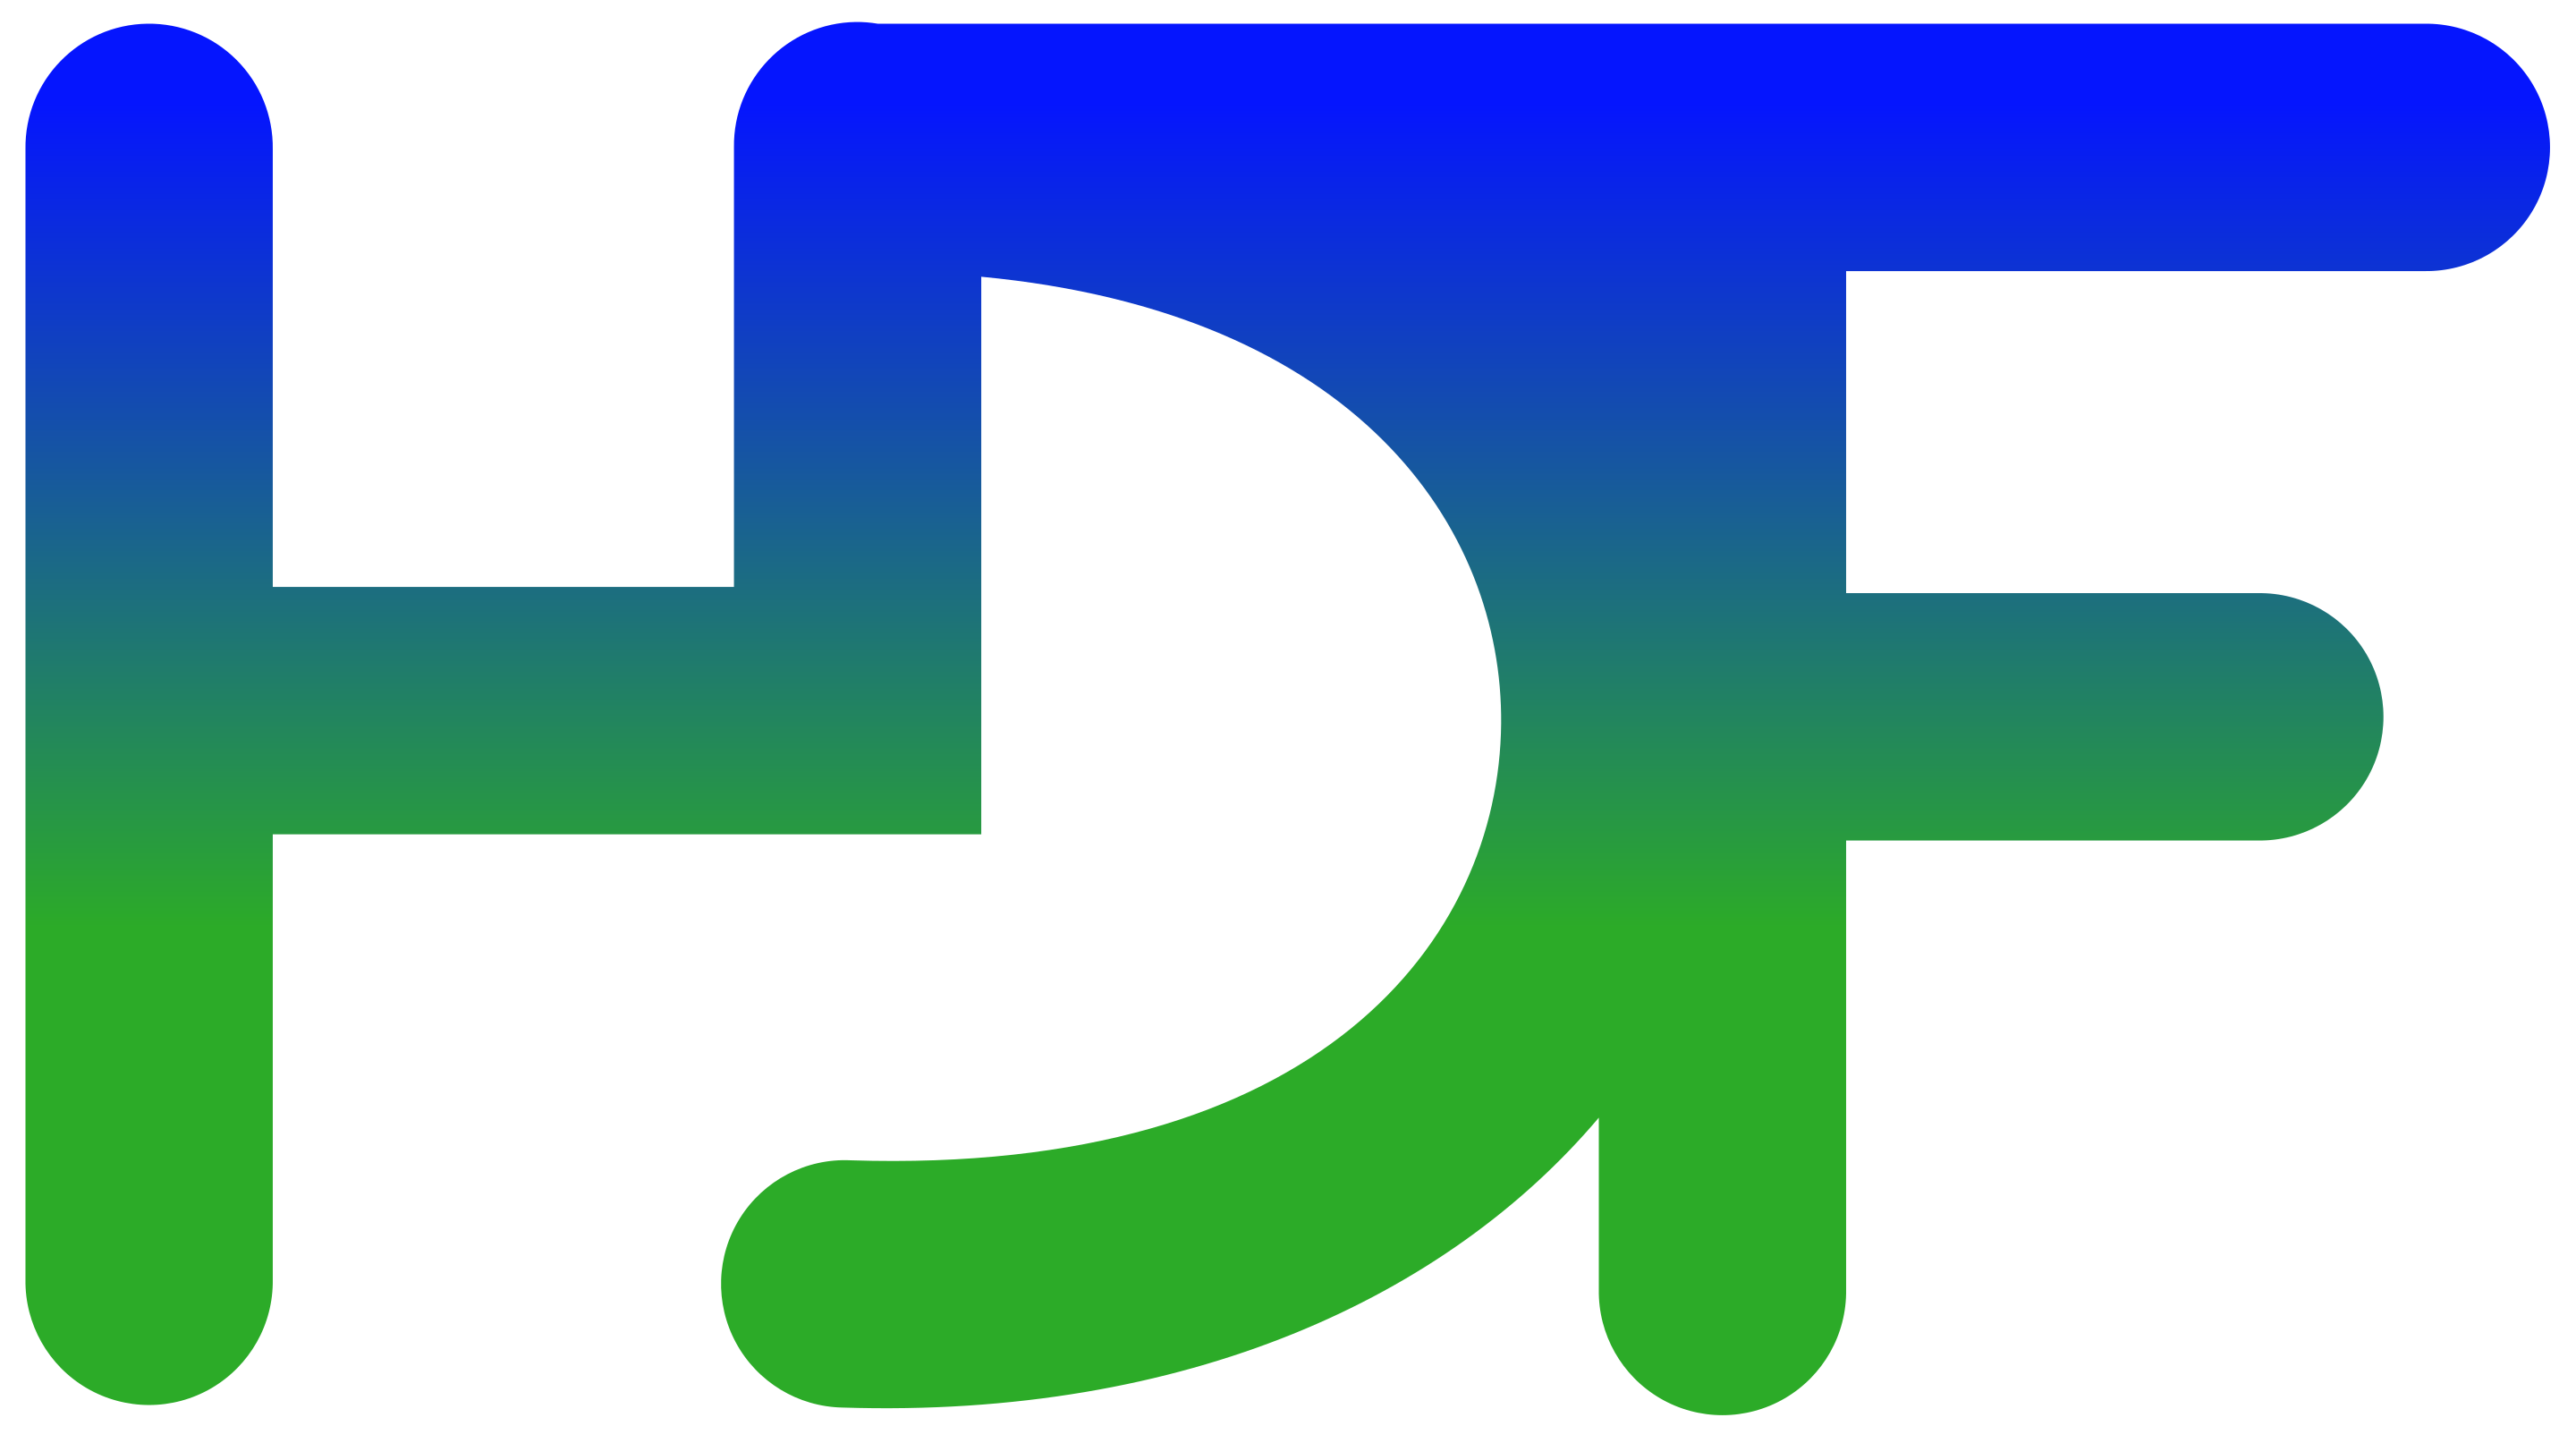

MATLAB has the ability to save neural networks and other machine learning models as a HDF5 file. To view more information, see the [link](https://www.mathworks.com/help/matlab/import_export/import-hdf5-files.html).

The model is saved with:

- Keras / TensorFlow model architecture (layers, nodes, connections) and configuration (hyper-parameters such as lbfgs or adam solver, loss function, epochs, early termination criteria)

- Weights that are adjusted during training and used for testing and validation

To download a Keras/TensorFlow model, you will need the following [Add-on Package](https://www.mathworks.com/matlabcentral/fileexchange/64649-deep-learning-toolbox-converter-for-tensorflow-models).

% download cracks.h5
file = 'cracks.h5';
url = 'http://apmonitor.com/pds/uploads/Main/cracks.h5';
outfile = websave(file,url);

% download concrete_crack.zip
url = 'http://apmonitor.com/pds/uploads/Main/concrete_cracks.zip';
filename = 'concrete_cracks.zip';
outfilename = websave(filename,url);

% Unzip then deleate zip folder
unziped_folder = unzip(filename);
delete(filename);

augmenter = imageDataAugmenter( ...
    'RandRotation',[0 360], ...
    'RandScale',[0.5 1]);

% Data processing
train_processor = imageDataAugmenter( ...
    'RandScale', [.8 1.2], ...
    'RandXReflection', true, ...
    'RandRotation', [-45, 145], ...
    'RandXShear', [0 45], ...
    'RandYShear', [0 45], ...
    'RandXTranslation', [-5 5], ...
    'RandYTranslation', [-5 5], ...
    'RandYReflection', true);
test_processor = imageDataAugmenter('RandScale', [.8 1.2]);

% Load data
train = imageDatastore('train\', 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess_con = augmentedImageDatastore([128,128],train);

% Load trained model
net = importKerasNetwork('cracks.h5');

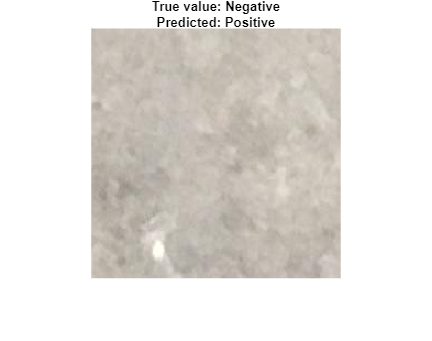


% Randomly select an image
btype = ["Positive", "Negative"]; % possible output values
rng('shuffle');
i=randi(2);
j=randi([19901,20000]);
b = btype(i);
im = strcat(lower(strrep(strcat(num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

% Show image
image_fp = test_image_filepath;
ime = imread(image_fp); % load image

% Modify image for Neural Network
im = double(imresize(ime,[128 128]));

% Display image with prediction
true_value = regexp(image_fp, "(Positive)|(Negative)", 'match');
figure('Position', [0,0,1000,1000])
imshow(ime);

% Create title string and display title
label =  "True value: " + string(true_value{1}) + "\n" + "Predicted: " + string(categorical(btype(net.classify(im))));
label = compose(label);
crack_title = title(label);

% Adjust the title position 
titlePos = get(crack_title, 'Position'); 
titlePos(2) = 2; % Adjust the title
set(crack_title, 'Position', titlePos, 'FontSize', 9);

#### Deploy Machine Learning: Logistic Regression

.mat files can be used to store machine learning models, data, scalars, or other objects needed to deploy an application on a server or other computer.

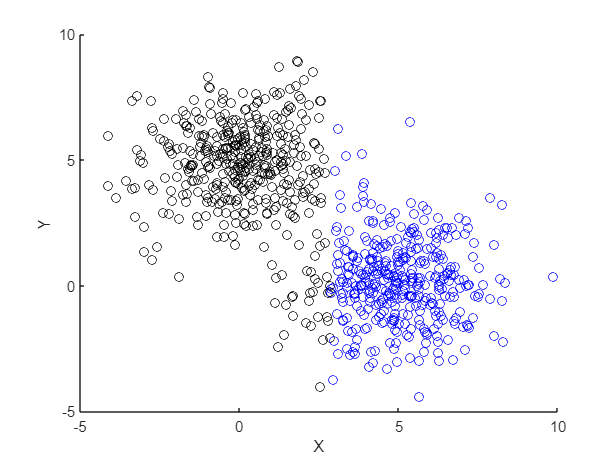

% Create Data
% Set parameters for data
n_samples = 800;
n_features = 2;
centers = [0, 5; 5, 0];
cluster_std = 1.5;

% Create matrixes to hold data
data_val = zeros(n_samples, n_features);
label = zeros(n_samples, 1);

% Create the random data based on previous inputs
for i = 1:2
    idx = ((i-1)*n_samples/2 + 1) : (i*n_samples/2);
    data_val(idx, :) = bsxfun(@plus, centers(i,:), cluster_std*randn(length(idx), n_features));
    label(idx) = i;
end

% Combine the X and Y data
tbl = [array2table(data_val) array2table(label)];
tbl.Properties.VariableNames = ["X","Y","label"];

% Plot Data
figure;
cmap = [0 0 0; 0 0 1];
colormap(cmap)
scatter(tbl,"X","Y","ColorVariable",true);

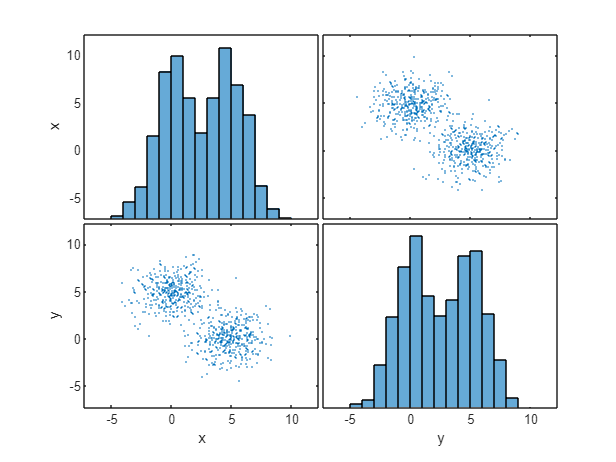

% Plot matrix
figure;
[~, ax, ~, ~, ~] = plotmatrix(table2array(tbl(:,1:end-1)));

% Add labels
xlabel(ax(2,1), 'x');
xlabel(ax(2,2), 'y');
ylabel(ax(1,1), 'x');
ylabel(ax(2,1), 'y');

% Split the data 80% training and 20% testing
[trainInd,~,testInd] = dividerand(n_samples,0.5,0,0.2);

train = tbl(trainInd,:);
test = tbl(testInd,:);

The model will be trained using the fitglm function, which creates a generalized linear regression model to predict the label based on the x and y inputs. 

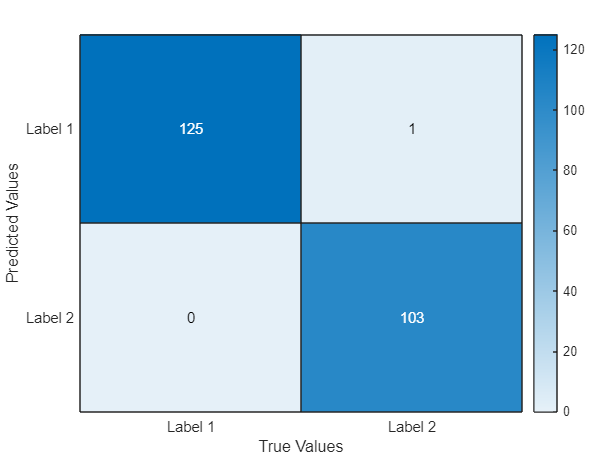

% Train model
model = fitglm(double(table2array(train(:,1:end-1))),categorical(table2array(train(:,end))-1),"Distribution","binomial");

% Store model and test data
store = {model,test};
save('store.mat','store');

% Load model and test data
loaded = load("store.mat",'store');
lr = loaded.store{1,1};
ltest = loaded.store{1,2};

% Predict using the loaded model and data
yp = categorical(int32(predict(model,double(table2array(ltest(:,1:end-1))))));

% Confusion Matrix
figure;
cmat = confusionmat(categorical(table2array(ltest(:,end))-1),yp);
heatmap(cmat,"YDisplayLabels", {'Label 1' 'Label 2'}, "XDisplayLabels", {'Label 1', 'Label 2'});
xlabel('True Values')
ylabel('Predicted Values')

#### Deploy Machine Learning: Number Identification

The next activity is to split a program that includes training and testing into two separate programs. Use a .mat file to store the test data and the neural network model.

Separate [**machine learning for number identification**](https://apmonitor.com/pds/index.php/Main/DeepLearningNeuralNetwork) into a training and test program. Show that the test program can predict the second to last number in the dataset.

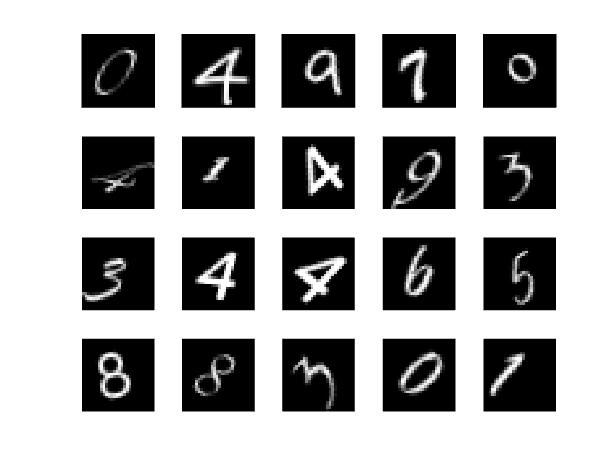

% Import dataset of numbers
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% Show example of dataset
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

n_samples = length(imds.Files);

% Extract the images into a matrix
X_data = cell(n_samples, 1);
for i = 1:n_samples
    [X_data{i}] = deal(reshape(readimage(imds,i)',[1,28*28]));
end
X_data = cell2mat(X_data);

% Save the labels of the images
Y_data = imds.Labels(1:n_samples);

% Split the data 50% training adn 50% testing
[trainInd,valInd,testInd] = dividerand(n_samples,0.5,0,0.5);

X_Train = X_data(trainInd,:);
X_Test = X_data(testInd,:);
Y_Train = Y_data(trainInd,:);
Y_Test = Y_data(testInd,:);

% Create fit
classifier = fitcnet(array2table(im2double(X_Train)),Y_Train);

% Store model and test data
store = {classifier,X_Test,Y_Test};
save('classifier.mat','store');

Below is an example that also shows a number from the test set that is evaluated with the Neural Network.

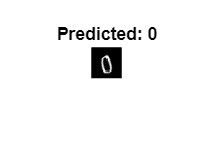

% Load model and test data
loaded = load("classifier.mat",'store');
lclassifier = loaded.store{1,1};
lx_test = loaded.store{1,2};
ly_test = loaded.store{1,3};

tbl = [array2table(im2double(lx_test)), array2table(ly_test)];

% Select random nummber image
n = randi([0,n_samples],1);

% Get the prediction
reshape(readimage(imds,n)',[1,28*28]);
yp = predict(classifier,im2double(reshape(readimage(imds,n)',[1,28*28])));

% Display the image with the prediction
figure;
imshow(imds.Files{n})
titleText = "Predicted: " + string(yp);
title(titleText, 'FontSize', 12)

Deploy Machine Learning: [Model Predictive Control Toolbox](https://www.mathworks.com/products/model-predictive-control.html)

% Create a discrete-time state-space model
A = -1/5;
B = 2;
C = 5;
D = 0;
Ts = 1;
sys = ss(A, B, C, D, Ts);

% Define the prediction and control horizons
N = 10;
Nu = 2;

% Create an MPC controller object
mpcobj = mpc(sys, Ts, N, Nu);

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.


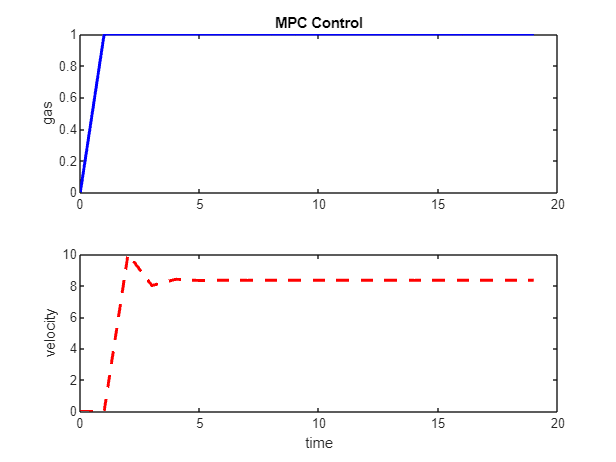


% Initialize the simulation
Tsim = 20;
Nsim = Tsim / Ts;
time1 = (0:Nsim-1) * Ts;
p1 = zeros(1, Nsim);
v1 = zeros(1, Nsim);

% Initial conditions
x = 0;

% Simulate the MPC controller
for k = 1:Nsim
    % Measure the current state
    y = C * x;
    
    % Set reference values
    % mpcobj.OutputVariables(1).setpoint = 40;
    
    % Compute MPC control action
    if k == 1
        u = 0;
    else
        u = mpcobj.Ts;
    end

    % Apply control action to the system
    x = A * x + B * u;
    
    % Store results
    p1(k) = u;
    v1(k) = y;
end

% Plot data
figure;
subplot(2,1,1);
plot(time1, p1, 'b-', 'LineWidth', 2);
ylabel('gas');
title('MPC Control');
subplot(2,1,2);
plot(time1, v1, 'r--', 'LineWidth', 2);
ylabel('velocity');
xlabel('time');

#### Deploy Machine Learning: Gekko MPC

[**Model Predictive Control (MPC)**](https://apmonitor.com/wiki/index.php/Main/Control) is an advanced control method to regulate and optimize dynamic systems. MPC uses time-based predictions to make adjustments that meet control objectives. The controller runs at a specified cycle time such as every second or minute. MPC is deployed with a data acquisition system to retrieve current process measurements, reoptimize the move plan, and send commands to acquators. The Gekko package uses combinations of [**physics-based**](https://gekko.readthedocs.io/en/latest/chemical.html), [**time-series**](https://gekko.readthedocs.io/en/latest/model_methods.html?highlight=arx#pre-built-objects), and [**machine learned models**](https://gekko.readthedocs.io/en/latest/brain.html) for predictions. In this example, the model is rebuilt if the HDF5 file does not exist. Otherwise, the HDF5 will be loaded and the MPC is solved again to create an updated move plan. Complete MPC instructions are provided with [**advanced temperature control**](https://apmonitor.com/do/index.php/Main/AdvancedTemperatureControl) of the TCLab.

Gekko is a Python package so this script uses Python code. To perform this code, you will need to install Anaconda and then open MATLAB from the Anaconda prompt. Simply open the Anaconda prompt and type MATLAB.

[Python in MATLAB](https://www.mathworks.com/products/matlab/matlab-and-python.html)

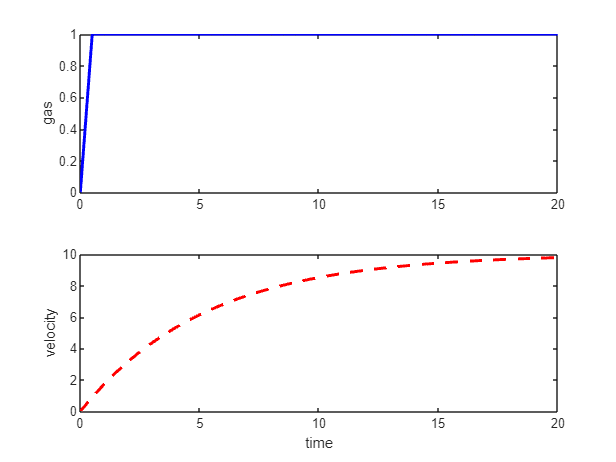

% start MATLAB from Anaconda prompt
clear; close all;

% Initialize Model
m = py.gekko.GEKKO();

if exist("gekko.h5",'file') == 2
    % load model from subsequent call
    time = h5read("gekko.h5","/time");
    p = h5read("gekko.h5","/p");
    v = h5read("gekko.h5","/v");
    
else
    % define model the first time
    m.time = linspace(0,20,41);
    
    p = m.MV(0,0,1);
    v = m.CV(0);
    m.Equation(5*v.dt() == -v + 10*p);
    m.options.IMODE = 6;
    p.STATUS = 1; p.DCOST = 1e-3;
    v.STATUS = 1; v.SP = 40; v.TAU = 5;
    m.options.CV_TYPE = 2;
    m.solve(disp=false);

    % Retrieving the values
    time = cellfun(@double,cell(m.time.tolist()));
    p = cellfun(@double,cell(p.VALUE.value));
    v = cellfun(@double,cell(v.VALUE.value));
    
    % save data in HDF5 file
    h5filename = 'gekko.h5';
    h5create(h5filename,'/time',size(time));
    h5write(h5filename,'/time',time);
    h5create(h5filename,'/p',size(p));
    h5write(h5filename,'/p',p);
    h5create(h5filename,'/v',size(v));
    h5write(h5filename,'/v',v);
end

% Plot data
figure();
subplot(2,1,1);
plot(time,p,'b-','LineWidth',2);
ylabel('gas');
subplot(2,1,2);
plot(time,v,'r--','LineWidth',2);
ylabel('velocity');
xlabel('time');

#### Further Reading

Learn more about the process of using deep learning effectively with [**A Practical Guide to Deep Learning: From Data to Deployment**](https://www.mathworks.com/campaigns/offers/practical-guide-to-deep-learning.html).

Learn more about utilizing your deep neural network on a larger scale with [**Deploying Deep Learning Models**](https://www.mathworks.com/videos/deep-learning-for-engineers-part-5-deploying-deep-learning-models-1617277371455.html).